clear all
syms c;
f=exp(-c);
xr(1)=double(subs(f,c,0));
iter(1) = 1;
imax = 10;
es=0.5;
ea(1)=100;
i = 1;

while abs(ea(i)) >= es && i < imax
    xr(i+1) = double(subs(f,c,xr(i)));
    iter(i+1) = i + 1;
    if xr ~= 0
        ea(i+1) = abs((xr(i+1)-xr(i))/xr(i+1))*100;
    end
    i = i + 1;
end

 table(iter',xr',ea','VariableNames',{'I','Xr','Ea'})

ans = 10×3 table
    I       Xr         Ea  
    __    _______    ______

     1          1       100
     2    0.36788    171.83
     3     0.6922    46.854
     4    0.50047    38.309
     5    0.60624    17.447
     6     0.5454    11.157
     7    0.57961    5.9034
     8    0.56012    3.4809
     9    0.57114    1.9308
    10    0.56488    1.1089


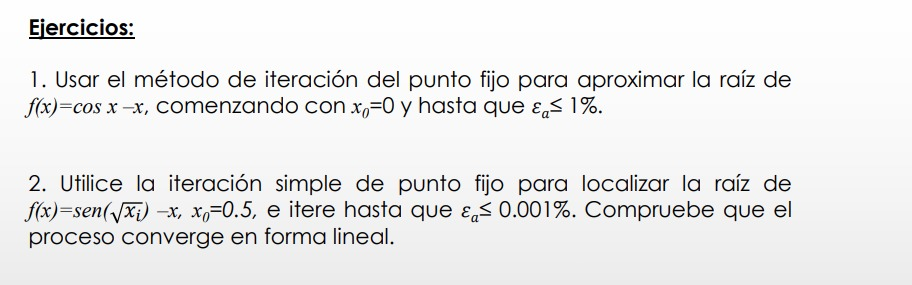

 
clear all
syms c;
f=cos(c);
xr(1)=double(subs(f,c,0));
iter(1) = 1;
imax = 30;
es=1;
ea(1)=100;
i = 1;

while abs(ea(i)) >= es && i < imax
    xr(i+1) = double(subs(f,c,xr(i)));
    iter(i+1) = i + 1;
    if xr ~= 0
        ea(i+1) = abs((xr(i+1)-xr(i))/xr(i+1))*100;
    end
    i = i + 1;
end

 table(iter',xr',ea','VariableNames',{'I','Xr','Ea'})

ans = 13×3 table
    I       Xr         Ea   
    __    _______    _______

     1          1        100
     2     0.5403     85.082
     3    0.85755     36.995
     4    0.65429     31.066
     5    0.79348     17.542
     6    0.70137     13.133
     7    0.76396      8.193
     8     0.7221     5.7966
     9    0.75042     3.7733
    10     0.7314     2.5996
    11    0.74424     1.7244
    12     0.7356     1.1735
    13    0.74143    0.78502


Ejercicio 2

clear all
syms c;
f=sin(sqrt(c));
xr(1)=double(subs(f,c,0.5));
iter(1) = 1;
imax = 30;
es=0.001;
ea(1)=100;
i = 1;

while abs(ea(i)) >= es && i < imax
    xr(i+1) = double(subs(f,c,xr(i)));
    iter(i+1) = i + 1;
    if xr ~= 0
        ea(i+1) = abs((xr(i+1)-xr(i))/xr(i+1))*100;
    end
    i = i + 1;
end

 table(iter',xr',ea','VariableNames',{'I','Xr','Ea'})

ans = 12×3 table
    I       Xr          Ea    
    __    _______    _________

     1    0.64964          100
     2    0.72152       9.9632
     3     0.7509       3.9123
     4     0.7621       1.4691
     5    0.76625      0.54177
     6    0.76777      0.19843
     7    0.76833     0.072496
     8    0.76853     0.026461
     9    0.76861    0.0096551
    10    0.76863    0.0035225
    11    0.76864    0.0012851
    12    0.76865    0.0004688
